**Correlación de señales**

La correlación es una opeación que se realiza entre dos señales

Varaibles de tiempo

N=10;
n=0:N;

Generación de dos funciones reales a partir de exponenciales complejas

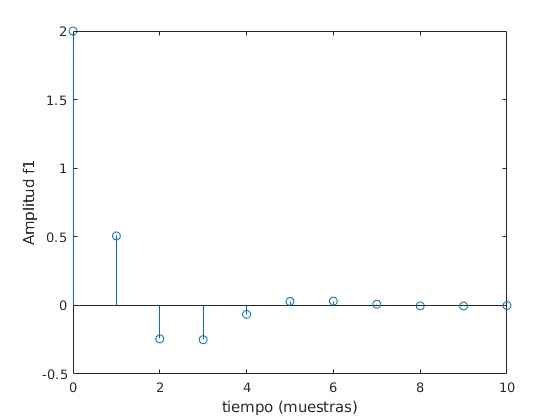

% parámetros función 1 (polares)
r1=0.5;
p1=1.04;
% parámetros función 2 (cartesianos)
re2=-0.4;
im2=0.5;

%Gráfica funcion 1 
f1=r1.^n.*(cos(p1*n)+1i*sin(p1*n)) + r1.^n.*(cos(p1*n)-1i*sin(p1*n));
figure
stem(n,f1)
xlabel('tiempo (muestras)')
ylabel('Amplitud f1')

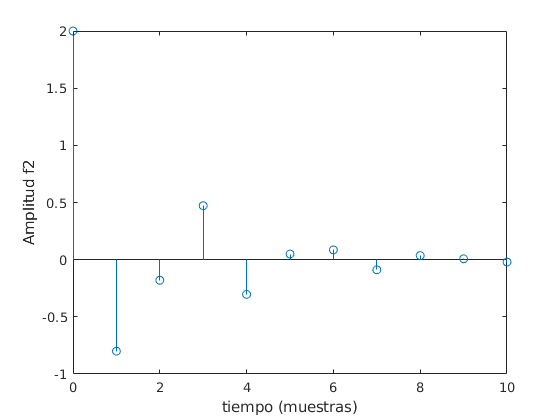


%Gráfica funcion 2
f2=(re2+1i*im2).^n + (re2-1i*im2).^n;
figure
stem(n,f2)
xlabel('tiempo (muestras)')
ylabel('Amplitud f2')

Correlación cruzada entre las dos señales

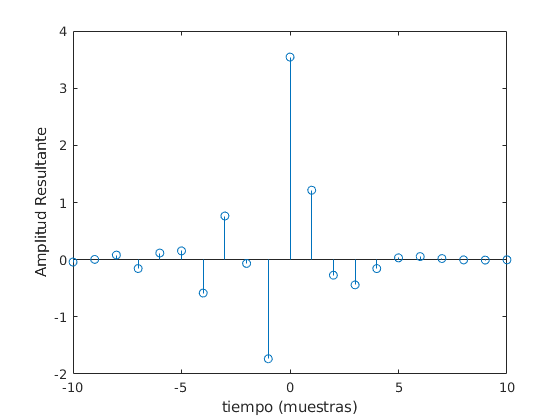

[Fcx,lag]=xcorr(f1,f2);
figure
stem(lag,Fcx)
xlabel('tiempo (muestras)')
ylabel('Amplitud Resultante')

La correlación no es una operación conmutativa. Observe el siguiente resultado y comparelo con el anterior

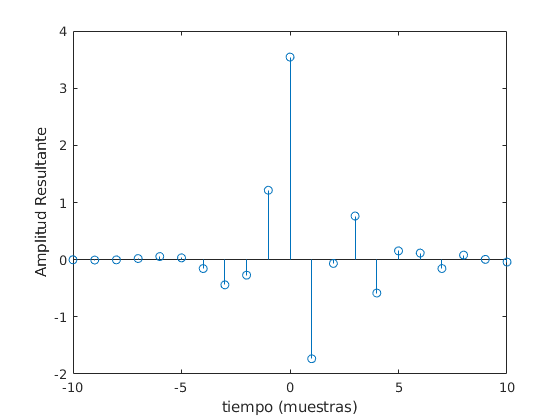

[Fcx2,lag2]=xcorr(f2,f1);
figure
stem(lag2,Fcx2)
xlabel('tiempo (muestras)')
ylabel('Amplitud Resultante')